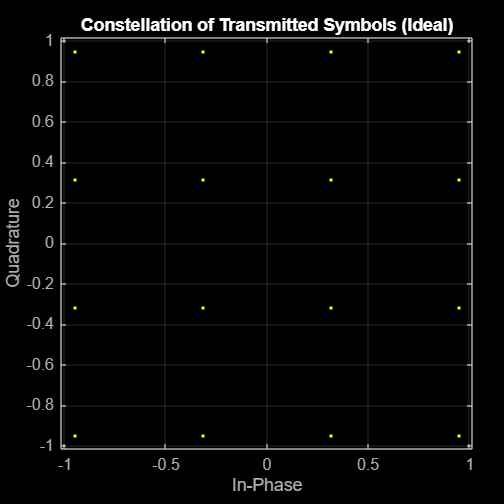

% Parameters
Nsubcarriers = 64;             % Number of subcarriers
cyclicPrefixLength = Nsubcarriers / 4;  % Length of cyclic prefix (1/4th of the OFDM symbol)
M = 16;                        % Modulation order (16-QAM)
Nbits = Nsubcarriers * 4;       % Number of bits (4 bits per subcarrier for 16-QAM)
SNR = 100;                      % Signal-to-Noise Ratio in dB

% Step 1: Data generation and mapping (16-QAM)
dataBits = randi([0 1], Nbits, 1);   % Random data bits
modulatedSymbols = qammod(bi2de(reshape(dataBits, [], log2(M))), M, 'UnitAveragePower', true); % 16-QAM modulation

% Plot ideal constellation before transmission
scatterplot(modulatedSymbols);
title('Constellation of Transmitted Symbols (Ideal)');
grid on;

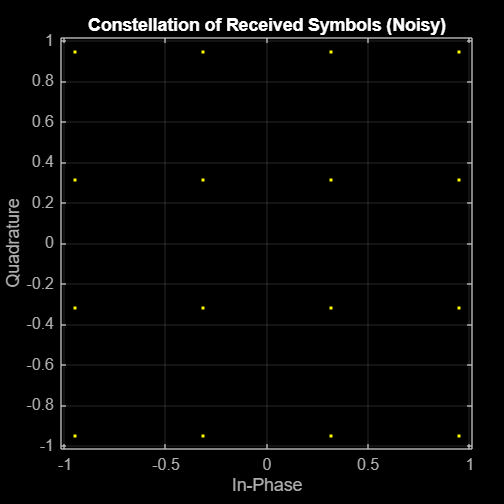


% Step 2: Serial to parallel conversion
parallelData = reshape(modulatedSymbols, Nsubcarriers, []);  % Reshape to Nsubcarriers x (Nbits / Nsubcarriers)

% Step 3: IFFT (convert frequency domain to time domain)
timeDomainSymbols = ifft(parallelData, Nsubcarriers);  % IFFT operation

% Step 4: Cyclic prefix addition
cyclicPrefix = timeDomainSymbols(end-cyclicPrefixLength+1:end, :);  % Take last part for CP
ofdmSymbolsWithCP = [cyclicPrefix; timeDomainSymbols];  % Append CP to each OFDM symbol

% Step 5: Parallel to serial conversion
serialData = ofdmSymbolsWithCP(:);  % Serialize the data for transmission

% Step 6: Transmission through AWGN channel
transmittedSignal = awgn(serialData, SNR, 'measured');  % Add white Gaussian noise

% OFDM Signal Reception
% Step 7: Serial to parallel conversion (reshape received data)
receivedParallelData = reshape(transmittedSignal, Nsubcarriers + cyclicPrefixLength, []);

% Step 8: Cyclic prefix removal
receivedSymbolsWithoutCP = receivedParallelData(cyclicPrefixLength+1:end, :);  % Remove cyclic prefix

% Step 9: FFT (convert time domain to frequency domain)
receivedFrequencyDomainSymbols = fft(receivedSymbolsWithoutCP, Nsubcarriers);  % FFT operation

% Step 10: Demapping (16-QAM demodulation)
receivedBits = reshape(de2bi(qamdemod(receivedFrequencyDomainSymbols(:), M, 'UnitAveragePower', true), log2(M)), [], 1);  % 16-QAM demodulation

% Calculate bit error rate (BER)
numErrors = sum(dataBits ~= receivedBits);  % Count bit errors
ber = numErrors / length(dataBits);         % Bit Error Rate (BER)

% Plot constellation of received symbols after transmission
scatterplot(receivedFrequencyDomainSymbols(:));
title('Constellation of Received Symbols (Noisy)');
grid on;


% Display results
disp(['Number of bit errors: ', num2str(numErrors)]);

Number of bit errors: 0


disp(['Bit Error Rate (BER): ', num2str(ber)]);

Bit Error Rate (BER): 0
